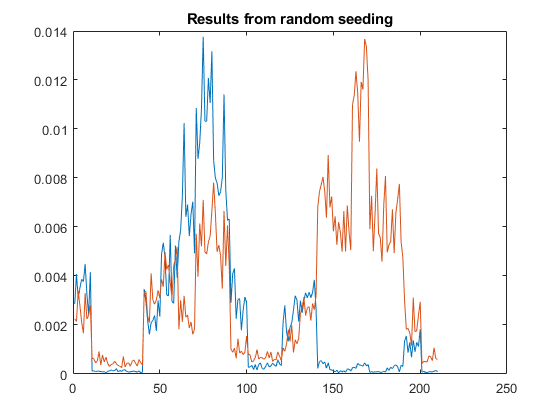

%% 1-results from random seeding
clear all
num_repeat = 10;

for i=1:num_repeat
    load(['data/overall_result_seed' num2str(i-1) '.mat']);
    index = [1 2 3 4 6 5 12 11  10 14 13 8 7 9 16 20 15 19 17 18 21]; % reordering for better illustration
    fn=featurenames(index);
    overall10cyc(:,i) = cyc10(index)'; overall50cyc(:,i) = cyc50(index)';
end
overall10cyc = overall10cyc';
overall50cyc = overall50cyc';

overall10cyc = overall10cyc(:);
overall50cyc = overall50cyc(:);

figure; plot(overall10cyc); hold on; plot(overall50cyc);
title('Results from random seeding')

fn

fn = 1×21 cell array
    {'Z'}    {'Roll'}    {'Pitch'}    {'Yaw'}    {'Homogeneity'}    {'Edensity'}    {'Vsratio'}    {'Sphericity'}    {'Elongation'}    {'RoughOuter'}    {'RoughInner'}    {'SurfOuter'}    {'SurfInner'}    {'Volume'}    {'PDensity'}    {'locElongation'}    {'Contact'}    {'locOri'}    {'DisNearest'}    {'locVolume'}    {'locSphericity'}


Subsampling

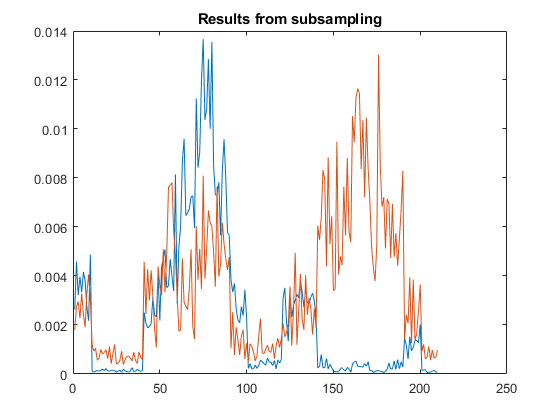

clear overall10cyc overall50cyc
for i=1:num_repeat
    load(['data/overall_result_seed_subset' num2str(i-1) '.mat']);
    index = [1 2 3 4 6 5 12 11  10 14 13 8 7 9 16 20 15 19 17 18 21];  % reordering for better illustration
    fn=featurenames(index);
    overall10cyc(:,i) = cyc10(index)'; overall50cyc(:,i) = cyc50(index)';
end
overall10cyc = overall10cyc';
overall50cyc = overall50cyc';

overall10cyc = overall10cyc(:);
overall50cyc = overall50cyc(:);
figure; plot(overall10cyc); hold on; plot(overall50cyc)
title('Results from subsampling')

fn

fn = 1×21 cell array
    {'Z'}    {'Roll'}    {'Pitch'}    {'Yaw'}    {'Homogeneity'}    {'Edensity'}    {'Vsratio'}    {'Sphericity'}    {'Elongation'}    {'RoughOuter'}    {'RoughInner'}    {'SurfOuter'}    {'SurfInner'}    {'Volume'}    {'PDensity'}    {'locElongation'}    {'Contact'}    {'locOri'}    {'DisNearest'}    {'locVolume'}    {'locSphericity'}
